# SVD, POD, ROM ? What else

## By prof. J. Morlier, SUPAERO

SVD is a common matrix-factorization algorithm in linear algebra that can be used as Reduced Order Model. One of the application is to interpolate fields through time (2D+time) using snapshots. By stacking 2D matrix in vector for each time step it becomes easy to use SVD.

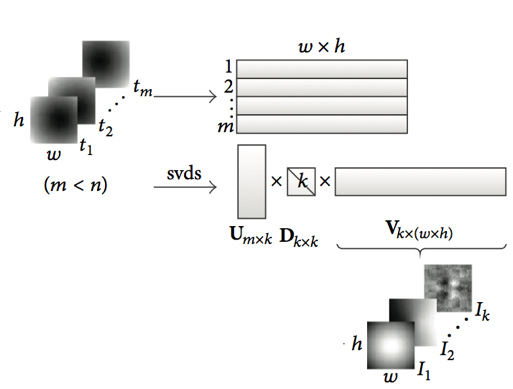 

Let's take a brief example of thermal field of a plate measured by 25 snapshots (produced every dt)

clear all;close all;

% time
Nt=25;
dt=1.0;
t = dt*[0:Nt-1]';

The spatial resolution of the sensor is Nx

% space Nx by Nx grid
Nx=20;
Nx2=Nx*Nx;
dx=1.0;
L = dx*(Nx-1);
x = dx*[0:Nx-1]';

% cook up data, Nt images, each Nx by Nx

We start by building simulated data and adding white noise (to reproduce experiments). It's called supervised approach as we build our simulated data (and we know HOW ! see next slides)

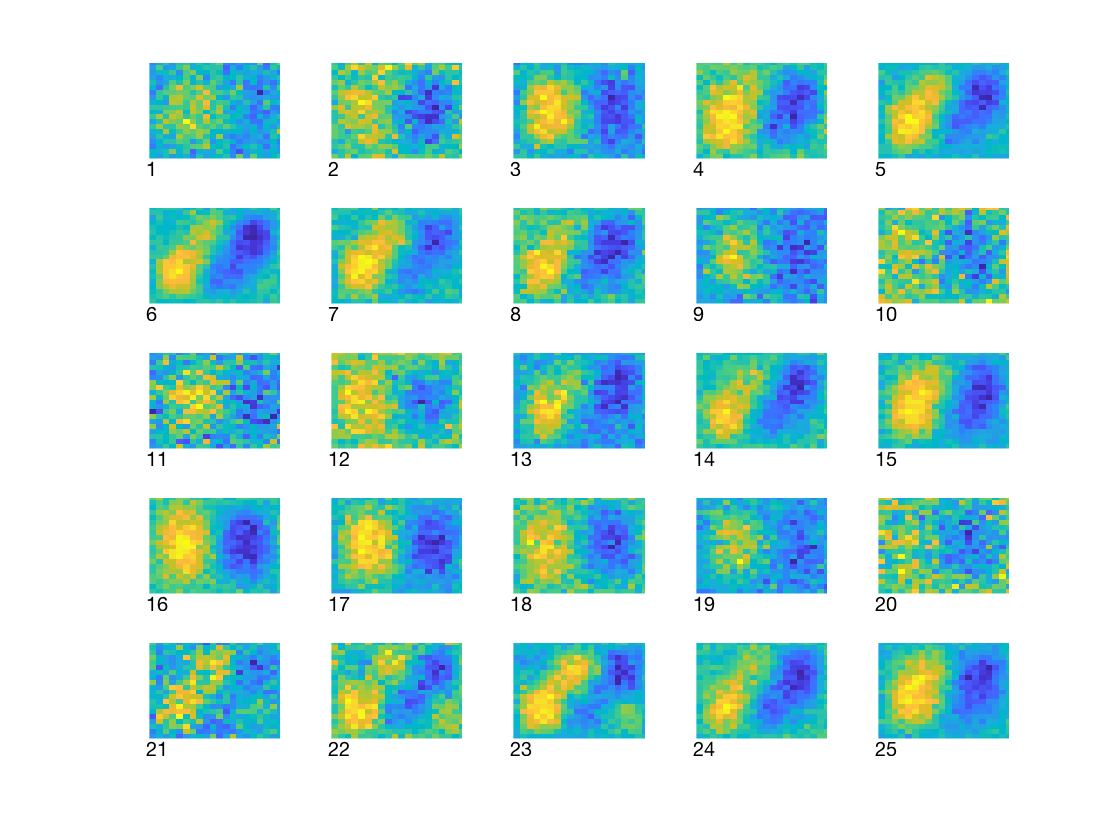

% build data from these modes
m0 = zeros(Nx,Nx);
m1 = zeros(Nx,Nx);
m2 = zeros(Nx,Nx);
mn = 0.1 * random('norm',0,1,Nx,Nx);
for p = [1:Nx]
for q = [1:Nx]
     m0(p,q) = sin(pi*x(p)/L).*sin(pi*x(q)/L);
     m1(p,q) = sin(pi*x(p)/L).*sin(2*pi*x(q)/L);
     m2(p,q) = sin(2*pi*x(p)/L).*sin(3*pi*x(q)/L);
end
end

% build data with modes with these amplitudes at different times
c0 = [1, -1, 1, -1, 1,   -1, 1, -1, 1, -1,     1, -1, 1, -1, 1,     -1, 1, -1, 1, -1,    1, -1, 1, -1, 1 ]';
c1 = [1, 2, 3, 4, 5,     5, 4, 3, 2, 1,        1, 2, 3, 4, 5,        5, 4, 3, 2, 1,      1, 2, 3, 4, 5 ]';
c2 = [0, 0, 0, 1, 2,     3, 2, 1, 0, 0,        0, 0, 1, 2, 1,        0, 0, 0, 0, 0,      1, 2, 3, 2, 1 ]';

% data is sum of modes with prescribed coefficients, plus random noise
figure(1);
clf;
hold on;
D = zeros( Nx, Nx, Nt );
for p = [1:Nt]
    D(:,:,p) = c0(p)*m0 + c1(p)*m1 + c2(p)*m2 + 0.7*random('norm',0,1,Nx,Nx);
    subplot(5,5,p);
    axis( [0 20 0 20] );
    axis off;
    hold on;
    imagesc(D(:,:,p));
    text(0,-1.5,sprintf('%d',p));
    hold on;
end

We rearrange Nx by Nx image Nx*Nx as row vector


S=zeros(Nt,Nx2);
for r = [1:Nt]
for p = [1:Nx]
for q = [1:Nx]
    s = Nx*(p-1)+q;
    S(r,s) = D(p,q,r);
end
end
end

% test of code to rebuild Nx by Nx image froom Nx*Nx row vector
if( 0 )
D2 = zeros( Nx, Nx, Nt );
for r = [1:Nt]
for s = [1:Nx2]
    p = floor( (s-1)/Nx+0.01 ) + 1;
    q = s - Nx*(p-1);
    D2(p,q,r) = S(r,s);
end
end
figure(2);
clf;
set(gca,'LineWidth',2);
for p = [1:Nt]
    subplot(5,5,p);
    axis( [0 20 0 20] );
    axis off;
    hold on;
    imagesc(D2(:,:,p));
    text(0,-1.5,sprintf('%d',p));
    hold on;
end
end

We use basic SVD analysis. For larger matrix, use 'eco' option of SVD.

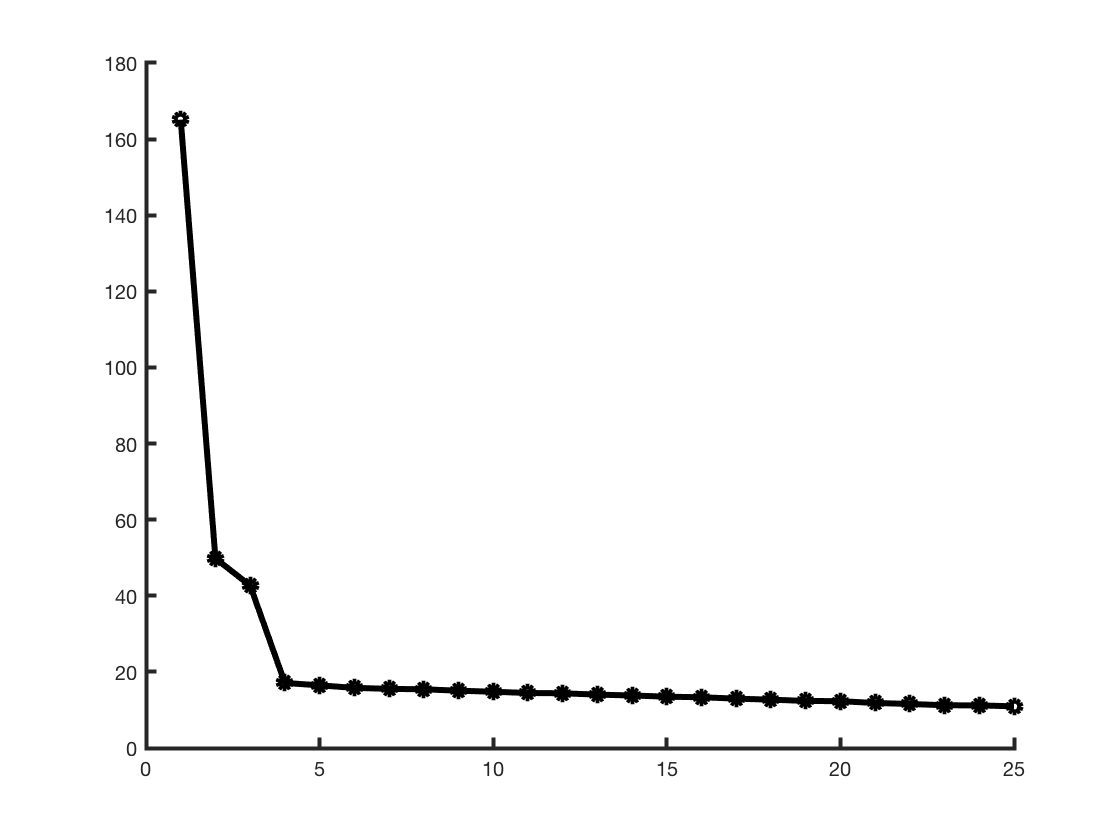


[U,LAMBDA,V] = svd(S);
C = U*LAMBDA;
S2 = C*(V');
evalue = spdiags(LAMBDA,0);

% plot eigenvalues
figure(3);
clf;
set(gca,'LineWidth',2);
hold on;
plot([1:Nt], evalue, 'k-', 'LineWidth',3);
plot([1:Nt], evalue, 'ko', 'LineWidth',3);


% test of code to rebuild D from S2=U*LAMBDA*V'=C*V'
if( 0 )
D3 = zeros( Nx, Nx, Nt );
for r = [1:Nt]
for s = [1:Nx2]
    p = floor( (s-1)/Nx+0.01 ) + 1;
    q = s - Nx*(p-1);
    D3(p,q,r) = S2(r,s);
end
end
figure(4);
clf;
for p = [1:Nt]
    subplot(5,5,p);
    axis( [0 20 0 20] );
    axis off;
    hold on;
    imagesc(D3(:,:,p));
    text(0,-1.5,sprintf('%d',p));
    hold on;
end
end

We select largest eigenvalues and reconstruct data from them

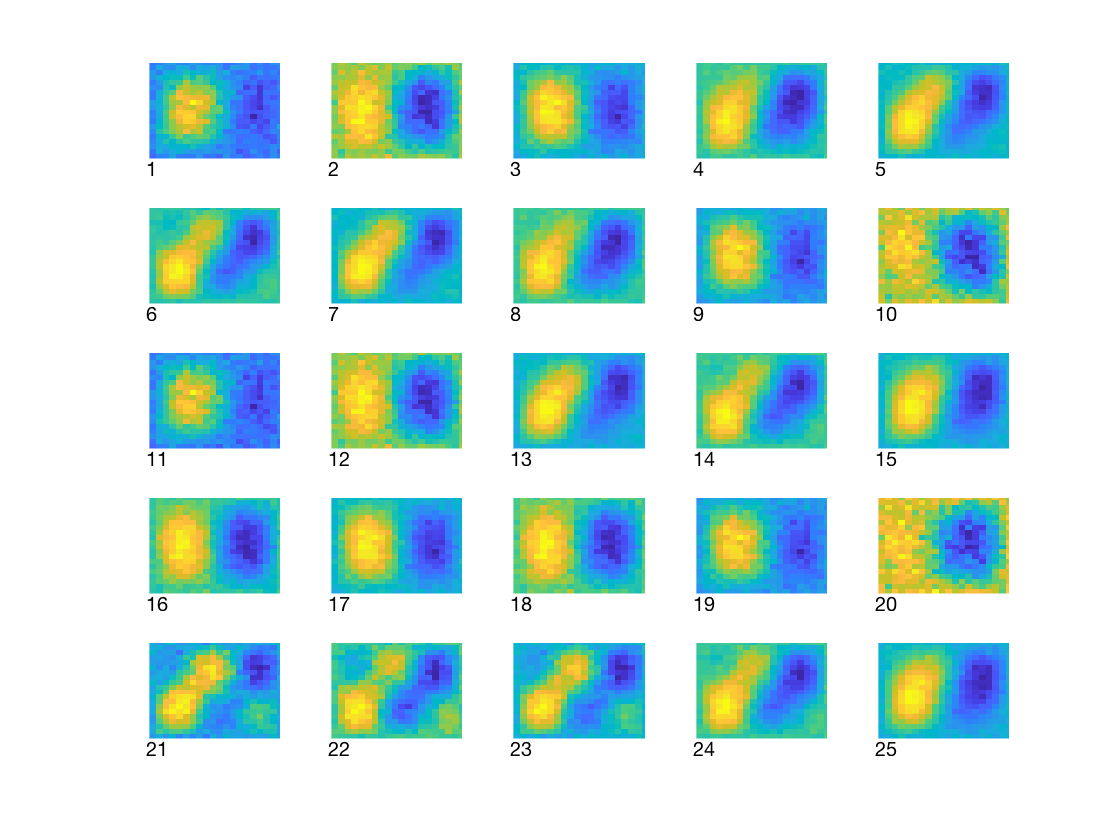


Nf=3;
Ua=U(:,1:Nf);
LAMBDAa=LAMBDA(1:Nf,1:Nf);
Ca = Ua*LAMBDAa;
Va = V(:,1:Nf);
Sa = Ca * (Va');

% retrieve images of modes from V matrix
M = zeros( Nx, Nx, Nt );
for r = [1:Nt]
for s = [1:Nx2]
    p = floor( (s-1)/Nx+0.01 ) + 1;
    q = s - Nx*(p-1);
    M(p,q,r) = V(s,r);
end
end

% plot reconstructed data
D4 = zeros( Nx, Nx, Nt );
for r = [1:Nt]
for s = [1:Nx2]
    p = floor( (s-1)/Nx+0.01 ) + 1;
    q = s - Nx*(p-1);
    D4(p,q,r) = Sa(r,s);
end
end
figure(4);
clf;
for p = [1:Nt]
    subplot(5,5,p);
    axis( [0 20 0 20] );
    axis off;
    hold on;
    imagesc(D4(:,:,p));
    text(0,-1.5,sprintf('%d',p));
    hold on;
end

We plot here the first Nf modes (truncation)

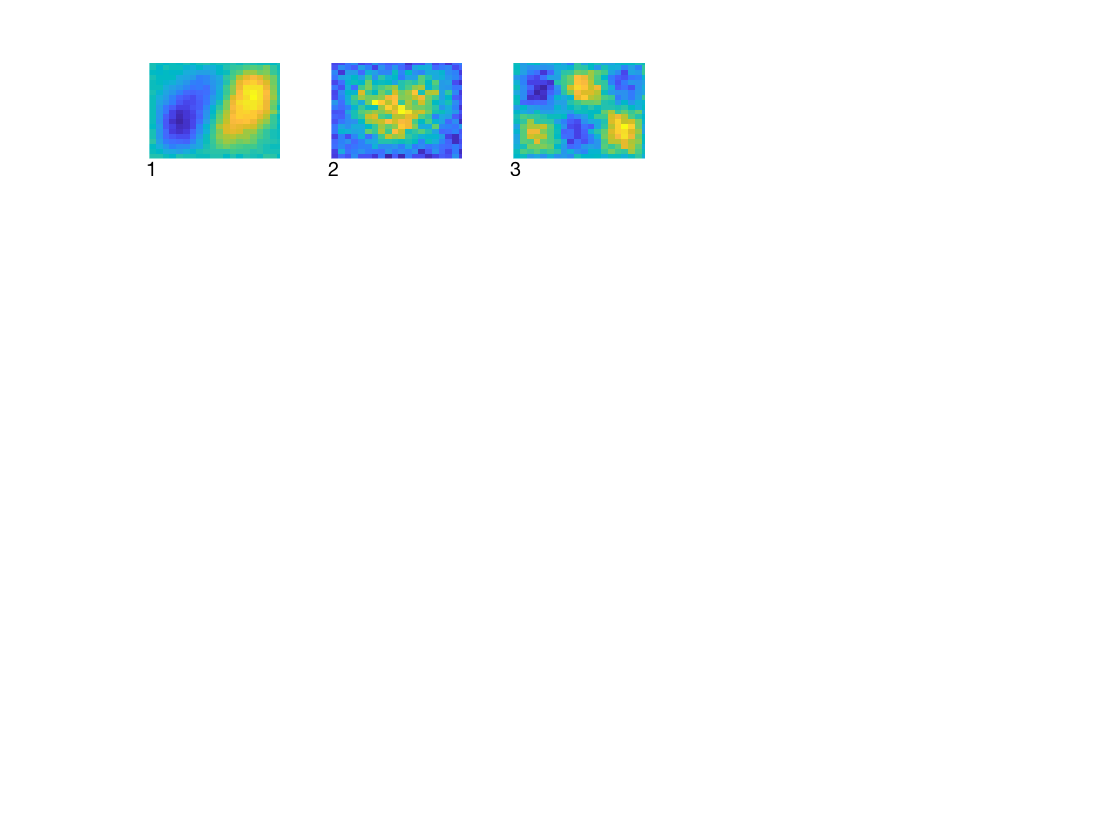

figure(5);
clf;
for p = [1:Nf]
    subplot(5,5,p);
    axis( [0 20 0 20] );
    axis off;
    hold on;
    imagesc(M(:,:,p));
    text(0,-1.5,sprintf('%d',p));
    hold on;
end

What is nice is that you can use the time series of coefficients of modes. POD interpolation in aerodynamics flow reconstruction uses this mathematical tool.

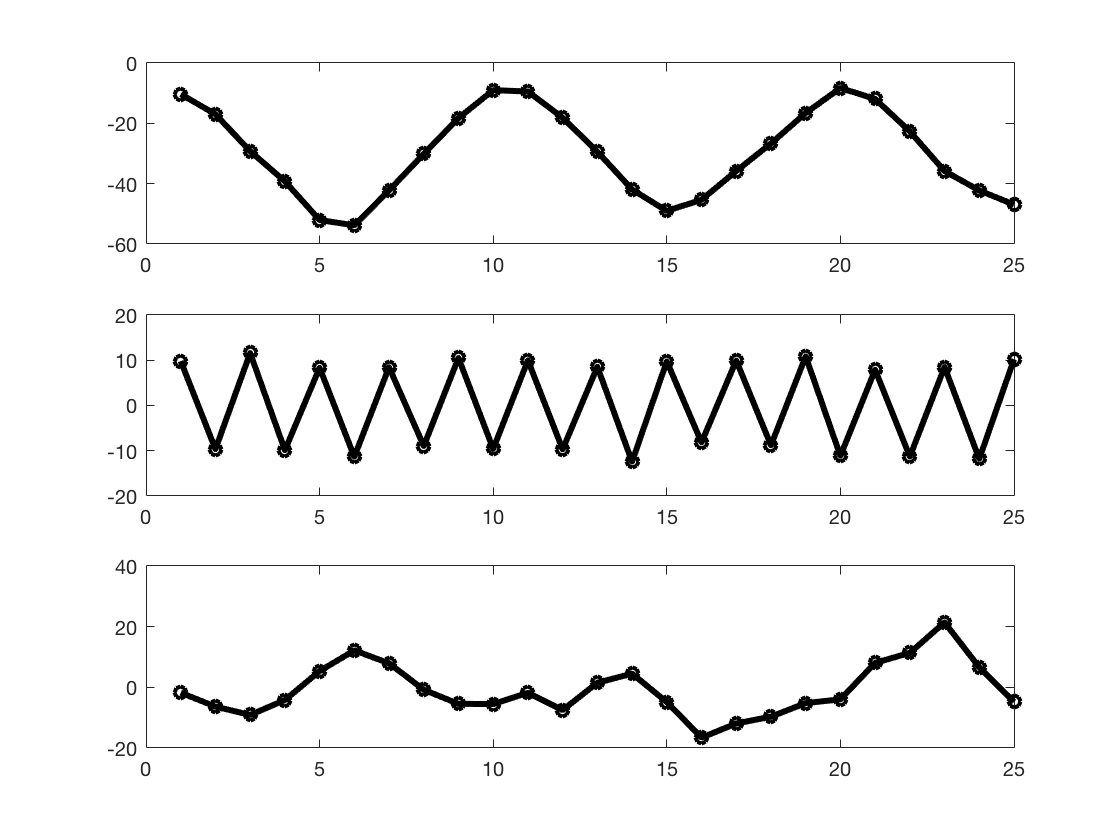

figure(6);
clf;
set(gca,'LineWidth',2);
for p = [1:Nf]
    subplot(Nf,1,p);
    plot( [1:Nt], Ca(:,p), 'k-', 'LineWidth', 3 );
    hold on;
    plot( [1:Nt], Ca(:,p), 'ko', 'LineWidth', 2 );
    hold on;
end


%That's all !